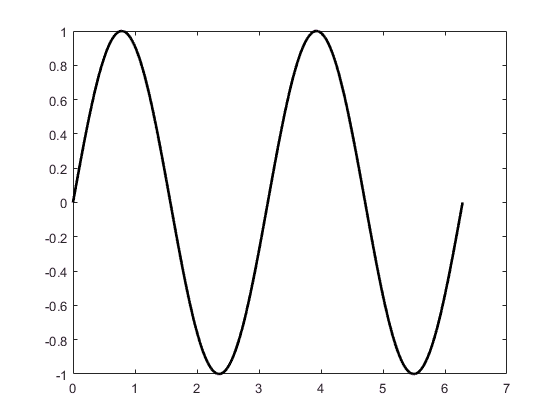

% Logical Indexing:
x = linspace(0,2*pi,1000);
y = sin(2*x);
plot(x,y,'k-','linew',2);
hold on

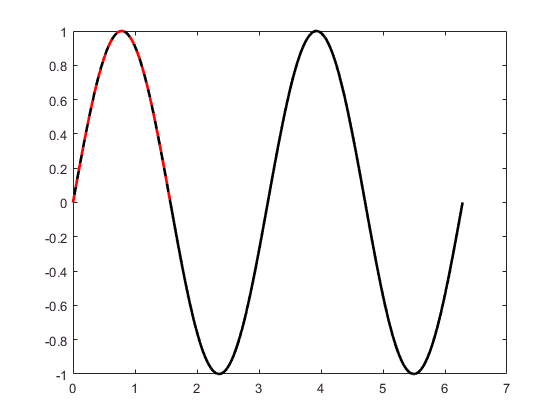

plot(x(x<pi/2),y(x<pi/2),'r--','linew',2)

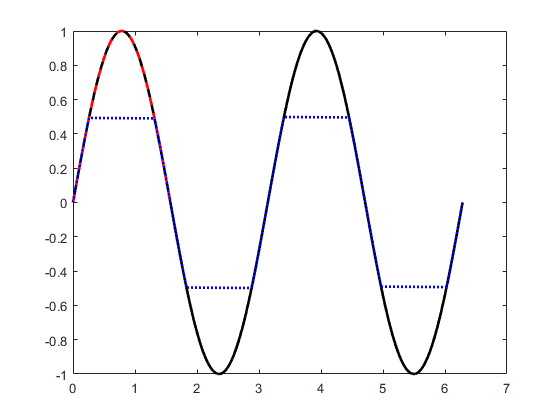

plot(x((y > -0.5)  & (y < 0.5)), y((y > -0.5)  & (y < 0.5)),'b:','linew',2)

% row-wise vs col-wise accessing
mat = ones(1000,1000); n = 1e6;
tic();
for i = 1:n, vec = mat(1,:); end
toc()

Elapsed time is 16.317489 seconds.



tic();
for i = 1:n, vec = mat(:,1); end
toc()

Elapsed time is 2.183588 seconds.


A = 1:18;
B = reshape(A,3,3,2);
C = B(:,1,:)

C = 
(:,:,1) =

     1
     2
     3


(:,:,2) =

    10
    11
    12


D = C(1:2:end)

D =      1     3    11


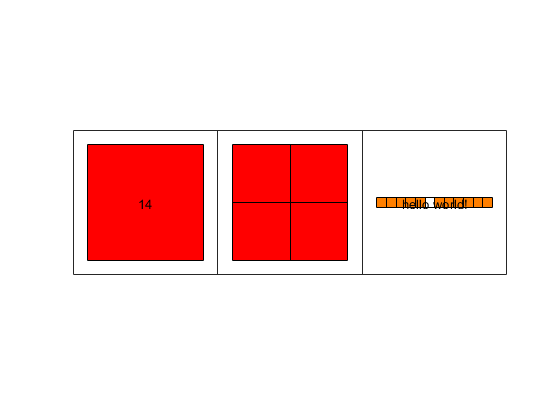

c = {14, [1,2;5,10], 'hello world!'};
cellplot(c)

c_num = [84.5, 91.0, 98.0, 80.5, 99.0, 100.0, 88.0];
s_data_1 = whos('c_num')

s_data_1 = struct with fields:
          name: 'c_num'
          size: [1 7]
         bytes: 56
         class: 'double'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


s_data_1.bytes

ans = 56

c = {84.5, 91.0, 98.0, 80.5, 99.0};
s_data = whos('c')

s_data = struct with fields:
          name: 'c'
          size: [1 5]
         bytes: 600
         class: 'cell'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


s_data.bytes

ans = 600

A = [ 84.5, 91.0, 98.0, 80.5, 99.0];
B = struct('grade',{84.5, 91.0, 98.0, 80.5, 99.0});
b = whos('B')

b = struct with fields:
          name: 'B'
          size: [1 5]
         bytes: 664
         class: 'struct'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


a = whos('A')

a = struct with fields:
          name: 'A'
          size: [1 5]
         bytes: 40
         class: 'double'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


A = struct('x',{1,2,3,4,5},'y',{1,3,5,4,2});
B = struct('x',{[1,2,3,4,5]},'y',{[1,3,5,4,2]});
a = whos('A')

a = struct with fields:
          name: 'A'
          size: [1 5]
         bytes: 1328
         class: 'struct'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


b = whos('B')

b = struct with fields:
          name: 'B'
          size: [1 1]
         bytes: 432
         class: 'struct'
        global: 0
        sparse: 0
       complex: 0
       nesting: [1×1 struct]
    persistent: 0


B(1)

ans = 1

c1 = struct('classname',{'Math', 'Physics', 'Bio'},'grade',{84.5, 91.0, 98.0});
c2 = struct('classname',{'English', 'Arts', 'Physics'},'grade',{90.1, 90.0, 80.0});
M = struct('name',{'Jane','Peter'},'academic',{c1,c2});
M(1).academic(3).grade

ans = 98

f = @(x) x.^3;
trap_rule(f,0,1,20)

ans = 0.2506

integral(f,0,1)

ans = 0.2500

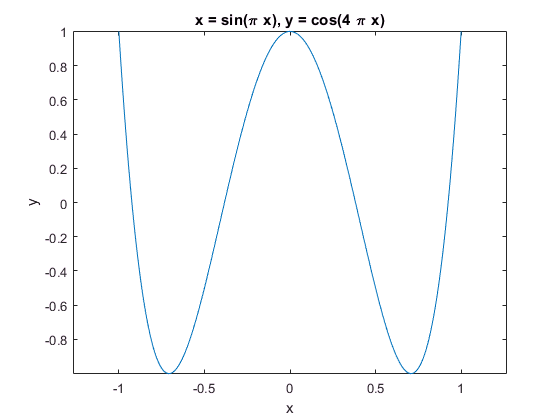

f1 = @(x) sin(pi.*x);
f2 = @(x) cos(4*pi.*x);
ezplot(f1,f2,[0,2])

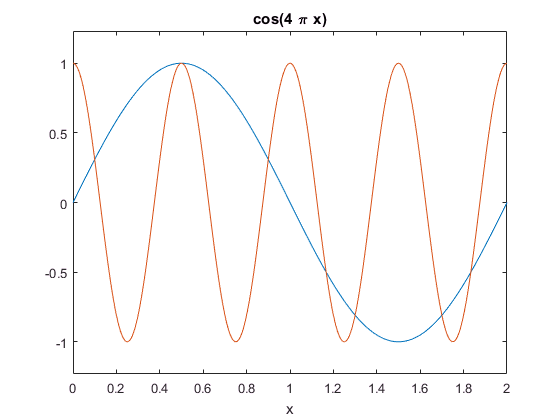

ezplot(f1,0,2)
hold on;
ezplot(f2,0,2)

trap_rule(@(x) 1./x,1,2.718,10)

ans = 1.0020